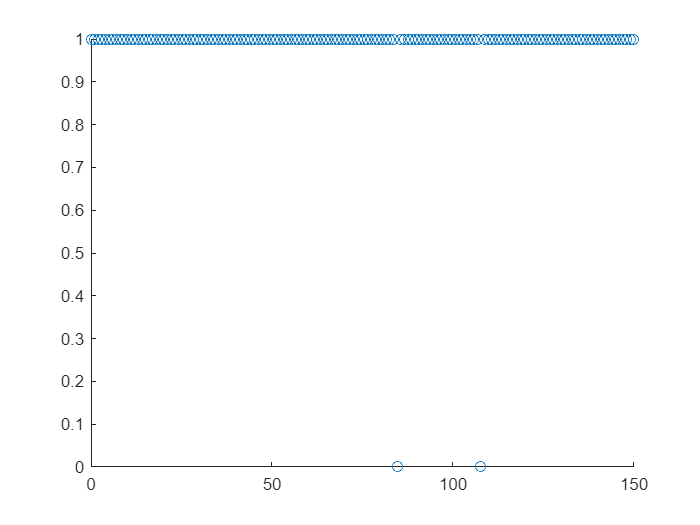

N = 150;
delta = 0.01*pi;
results = zeros(N,10);
w=warning('off','all');
set_param('non_linear_control_complete',"FastRestart","on")

for i=1:N
    initial_conditions_1 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_2 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_3 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    

    initial_conditions_trans = state_transformation([0,0,0], initial_conditions_1);
    initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
    initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

    out = sim('non_linear_control_complete',"StopTime","10");
    warning(w);
    check_convergence = out.check.signals.values(end,1);
    
    results(i,:) = [initial_conditions_1 initial_conditions_2 initial_conditions_3 check_convergence];
end

x = linspace(0, N, N);

figure
scatter(x,results(:, 10), "Marker","o")

r = 12;

initial_conditions_1 = results(r,1:3);

'results' requires Fixed-Point Designer.

initial_conditions_2 = results(r,4:6);
initial_conditions_3 = results(r,7:9);

initial_conditions_trans = state_transformation([0,0,0], initial_conditions_1);
initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);